# Adaptive Machine Learning for Dynamic Radiolocation

## Problem Background

Indoor radiolocation systems face a significant challenge in environments that frequently change, where factors such as the repositioning of base stations, movement of large objects affecting radio propagation, body shadowing, and high foot traffic can significantly alter signal behavior [1]. These conditions are common in urban settings and real-world indoor environments, making accurate location estimation difficult. This project aims to develop adaptive machine learning techniques capable of maintaining high accuracy in radiolocation systems, even in dynamic environments where significant changes occur.

Previous work addressing these challenges faced in indoor radiolocation includes a UVIC PhD project involving an autonomous drone that periodically updates the survey data used to estimate the location of mobile devices [2]. This autonomous robot successfully traced a predefined path to collect wireless packets and produced a database of RSSI and CSI fingerprints alongside a 2D LIDAR map of the floor. While effective, this solution has significant limitations: data collection is time-consuming and can only occur infrequently, often restricted to once a night or, more realistically, once a month. In dynamic in-building environments, this can lead to outdated or inaccurate survey data, compromising the precision of location estimates as environmental changes occur daily.

The goal of this project is to develop a neural network that improves indoor localization in Wireless Local Area Networks (WLANs) by utilizing received signal strength (RSS) data from multiple wireless access points (WAPs), a solution that has been proposed for various mobile computing applications [1]. This WLAN terminal location technique offers several advantages: it does not require additional measurement hardware, it operates without the need for strict synchronization between base stations, and it can be implemented across various cellular network configurations with minimal adjustments [1]. Rather than creating a new WLAN location estimation algorithm, this research focuses on designing an adaptive machine learning method capable of adjusting to environmental changes. By doing so, it eliminates the need for constant re-collection of survey data whenever the environment or base station locations are altered. A single calibration set will serve as the reference, enabling accurate and efficient location-aware computing inside buildings without the need for repeated data collection.

## Simulation Environment and Dataset Configuration

A simulation environment must be defined with randomly generated data points to use for the initial development and testing of the project. The initial simulation environment consists of a 100m x 100m grid, with no obstacles. Four base stations are located at (25, 25), (25, 75), (75, 25), and (75, 75). Random sample data points will be generated, which will include three parameters: an x-coordinate, a y-coordinate, and an RSS measurement vector corresponding to its position relative to each base station in the simulation environment. To account for the non-linear distribution of signal propagation and attenuation [3], each RSS measurement vector has a path loss vector, which represents the measured path loss value in decibels corresponding to the location of a given survey data point. The measured path loss values are modeled using the path loss formula for isontropic antennas expressed in terms of decibels:

#### 
$$\textrm{PL}=g\left(\theta \right)+V$$


#### 
$$g\left(\theta \right)=20\;\log_{10} {\left(\frac{4\pi \textrm{df}}{c}\right)}$$


#### 
$$V\;\sim \;N\;\left(\;0\;,\;\sigma^2 \;\right)\;$$


where *g*($\theta$) is a vector function which gives the true median path loss values for locations $\theta$ [3], $d$ is the distance between the nearest base station transmitter and mobile reciever, $f$ is the signal frequency, and $c$ is the speed of light [4]. *V* is a zero-mean random error vector that is independent of the location $\theta$. It is cruical to account for the radio path loss within the model to simulate the real-world attenuation of radio signals, providing a realistic RSS estimate at any given location. The randomly generated values within the simulation are treated as 100% accurate. These values represent a real-life dataset, as if collected from a mobile device measuring RSS from multiple WAPs at a mobile terminal.

% Simulation environment parameters
grid_size = 100;           % Size of grid (100m x 100m)
base_stations = [25, 25;   % Base station location 1
                 25, 75;   % Base station location 2
                 75, 25;   % Base station location 3
                 75, 75];  % Base station location 4

% Location Measurements (2xN)
Y_train = grid_size * rand(800, 2); % Training Data Set
Y_valid = grid_size * rand(100, 2); % Validation Data Set
Y_eval = grid_size * rand(100, 2); % Evaluation Data Set

% Path loss model parameters
A = -30;   % RSS at reference distance of 0m (perfect signal connection), in dBm
f = 2.4e9; % Frequency in Hz (2.4 GHz for WLAN/WiFi)
c = 3e8;   % Speed of light in m/s

% RSS Measurements (4xN)
X_train = zeros(800, 4); % Training Data Set
X_valid = zeros(100, 4); % Validation Data Set
X_eval = zeros(100, 4); % Evaluation Data Set
for ii = 1 : 4
    
    % Compute Euclidean distance to the base station
    distance_to_bs_train = sqrt( sum( abs( base_stations( ii , :) - Y_train ).^2 , 2 ) );
    distance_to_bs_valid = sqrt( sum( abs( base_stations( ii , :) - Y_valid ).^2 , 2 ) );
    distance_to_bs_eval = sqrt( sum( abs( base_stations( ii , :) - Y_eval ).^2 , 2 ) );

    % Apply path loss model (gaussian noise with variance = 1)
    X_train(:, ii) = A - 20 * log10(4 * pi * distance_to_bs_train * f / c) + (1 * rand);
    X_valid(:, ii) = A - 20 * log10(4 * pi * distance_to_bs_valid * f / c) + (1 * rand);
    X_eval(:, ii) = A - 20 * log10(4 * pi * distance_to_bs_eval * f / c) + (1 * rand);

end

## WLAN Terminal Localization Algorithm

### Parzen Window Estimator Method - Validation

The aim of this section is to carry out a cross-validation procedure, as described in [1], [5], to determine the optimal kernel width for use in a Parzen Window Estimator. This estimator, detailed in [1], [6], is employed as an approximation to the Minimum Mean Square Error (MMSE) estimator for predicting location coordinates based on RSS measurements. The kernel width is a crucial parameter in Parzen Windows, directly impacting the accuracy of the location estimates derived from RSS data.

To find the optimal kernel width, a range of kernel widths, selected from the recommended search spaces in [5], are systematically tested to identify the one that minimizes the MSE in the location estimates. Each kernel width within this range is assessed using a Leave-One-Out Cross Validation technique [7]. In each iteration, a specific survey point is omitted from the dataset, treating it as a validation point. The remaining data points serve as the training set from which weights for the Parzen Window Estimator are calculated using a Gaussian kernel.

For each left-out point, the location estimate is calculated as a weighted sum of the coordinates of the training points, where weights are based on the similarity of RSS values between the training and validation points. The squared error between the estimated location and the actual location of the omitted point is then calculated and accumulated across all survey points for the current kernel width to obtain the cross-validation MSE. For a sufficiently large survey set, the optimal kernel width is determined by finding the one that produces the minimum cross-validation MSE, indicating the best fit for the location estimation model [5]. 

% Define range of kernel widths to test
h_vector = 0.01 : 0.001 : 2;

% Initialize vector to store cross-validation MSE values for each kernel width
MSE_valid = zeros( size( h_vector ) );

% Perform Leave-One-Out Cross Validation for each kernel width
for hh = 1 : length( h_vector )
    
    % Test current kernel width
    h_value = h_vector( hh );

    % Estimate the weights using Gaussian kernel based on RSS similarity
    weights_valid = gaussian_kernel(X_valid, X_train, h_value);

    % Compute estimated locations
    Y_est = zeros( length(X_valid) , 2 );
    for nn = 1 : length( X_valid )

        % Estimate the location using weighted sum of training locations
        Y_est( nn , : ) = sum( weights_valid( nn , : ) .* Y_train.' , 2 );

    end

    % Compute cross-validation MSE
    MSE_valid( hh ) = mean( sum( abs( Y_est - Y_valid ).^2 , 2 ) );

end

% Find the kernel width which gave the best MSE performance
[ ~ , h_best_idx ] = min( MSE_valid );
h_best = h_vector( h_best_idx );
fprintf('Opitmal kernel width: %.6f\n', h_best);

Opitmal kernel width: 0.702000


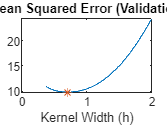

plot( h_vector , MSE_valid , '-' , h_best , MSE_valid( h_best_idx ) , '*' );
title('Mean Squared Error (Validation)');
xlabel('Kernel Width (h)');

### Parzen Window Estimator Method - Evaluation

After obtaining the optimal kernel width during the Cross Validation process, all components required to implement the PWE method for performing localization have been obtained. This optimal kernel width is used to evaluate the Parzen Window Estimator on a separate evaluation set, producing an overall evaluation MSE that reflects the method’s accuracy.

% Estimate the weights using Gaussian kernel based on RSS similarity
weights_eval = gaussian_kernel(X_eval, X_train, h_best);

% Compute estimated locations
Y_est = zeros( length(X_eval) , 2 );
for nn = 1 : length( X_eval )

    % Estimate the location using weighted sum of training locations
    Y_est( nn , : ) = sum( weights_eval( nn , : ) .* Y_train.' , 2 );

end

% Compute cross-validation MSE
MSE_eval = mean( sum( abs( Y_est - Y_eval ).^2 , 2 ) );
fprintf('Parzen Window Method - Evaluation MSE: %.6f\n', MSE_eval);

Parzen Window Method - Evaluation MSE: 8.812738


### Neural Network Method

The neural network method is constructed using a feedforward network with one hidden layer of 10 nodes. The network is trained on the training dataset using the measured RSS values as inputs and the location coordinates as outputs. After training, the network is tested on the evaluation dataset, with location predictions generated for each RSS measurement. The MSE between the predicted and actual locations in the evaluation dataset is computed as the performance metric, providing an alternative measure of accuracy to compare against the Parzen Window Estimator.

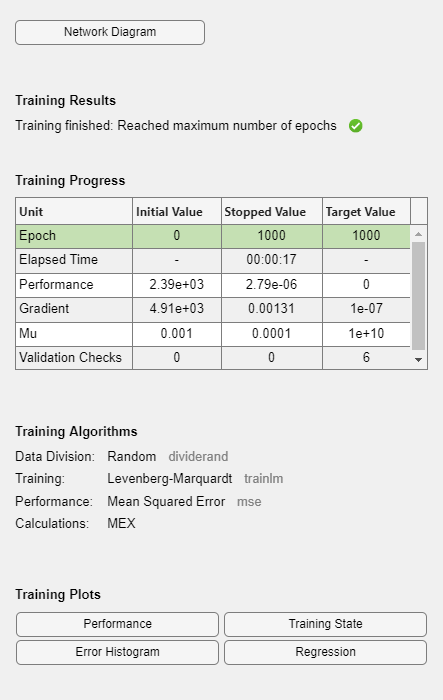

% Construct a feedforward network with one hidden layer of size 10.
net = feedforwardnet(10);

% Train the network
[net, tr] = train(net, X_train', Y_train');

% Test the network
Y = net(X_eval');

% Calculate performance
perf = perform(net, Y, Y_eval');

% Display the evaluation MSE
fprintf('Evaluation MSE using Neural Network Localization Method: %.8f\n', perf);

Evaluation MSE using Neural Network Localization Method: 24.50513278


## Comparative Testing for Different System Parameters

The aim of this section is to validate the effectiveness of the Parzen Window Estimator method for localization by comparing its MSE with that of a Neural Network model across different simulation parameters. The primary goal is to understand how the accuracy of both models changes with varying levels of signal variance and sample size.

### Accuracy vs. Variance

In this test, the variance of the RSS vector was incrementally adjusted to simulate varying levels of signal attenuation. After 100 epochs of localization processing for each variance, the average MSE was calculated for both the PWE and NN models at each level of RSS vector variance. The results are as follows:

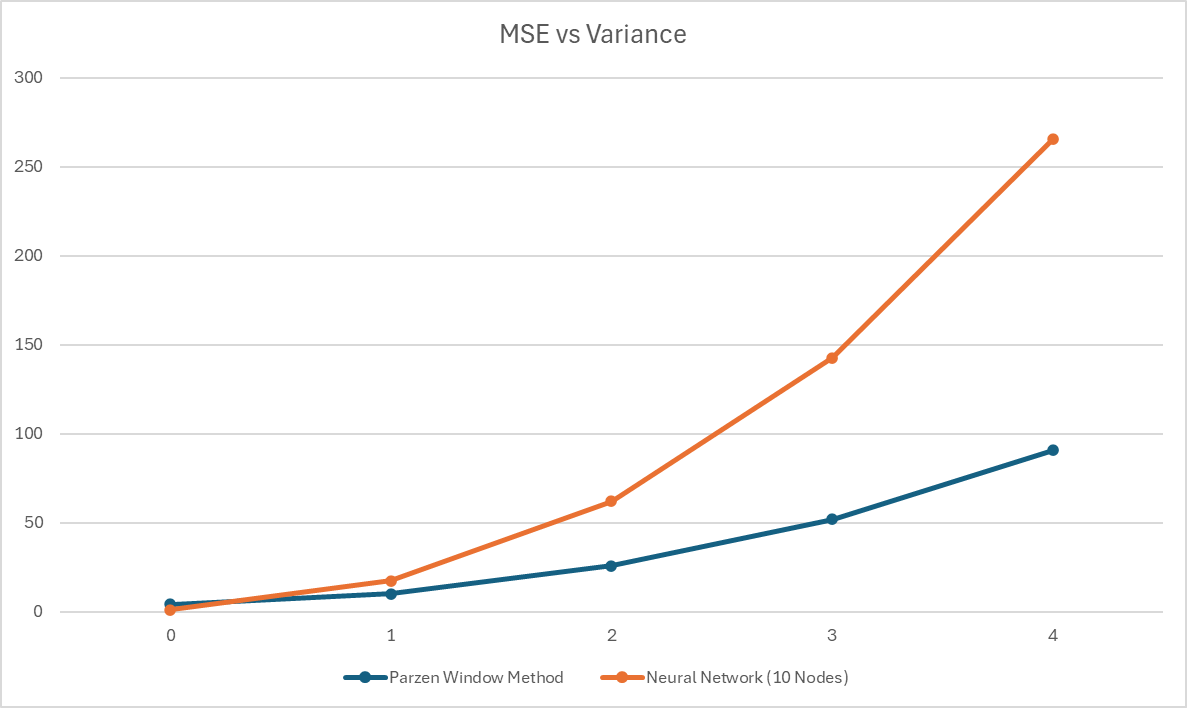

From the results, it can be observed that both the PWE and NN models experience a significant increase in MSE as the variance of the RSS vector increases, indicating that both models struggle more as signal noise and attenuation become more prevalent. When the variance is zero, the NN model outperforms the PWE model, achieving a significantly lower MSE. However, as the variance increases, the MSE for both models increases, with the NN model showing an exponential increase. For example, at a variance of 4, the PWE model's MSE is 90.7186, while the NN model’s MSE reaches 265.4620. This suggests that the PWE model is more stable under varying levels of signal attenuation, whereas the NN model becomes less accurate as the noise in the data increases, possibly due to overfitting or difficulty generalizing to noisy data.

The relative stability of PWE's performance as compared to the NN model suggests that PWE may be better suited for environments where signal attenuation and noise are higher, offering more reliable performance under such conditions.

### Accuracy vs. Sample Size

In this test, the sample size used in the validation and evaluation processes are incrementally adjusted to determine its impact on the accuracy of the models. After 10 epochs of localization processing for each sample size at a fixed variance of 1, the average MSE is calculated for both models. The results are as follows:

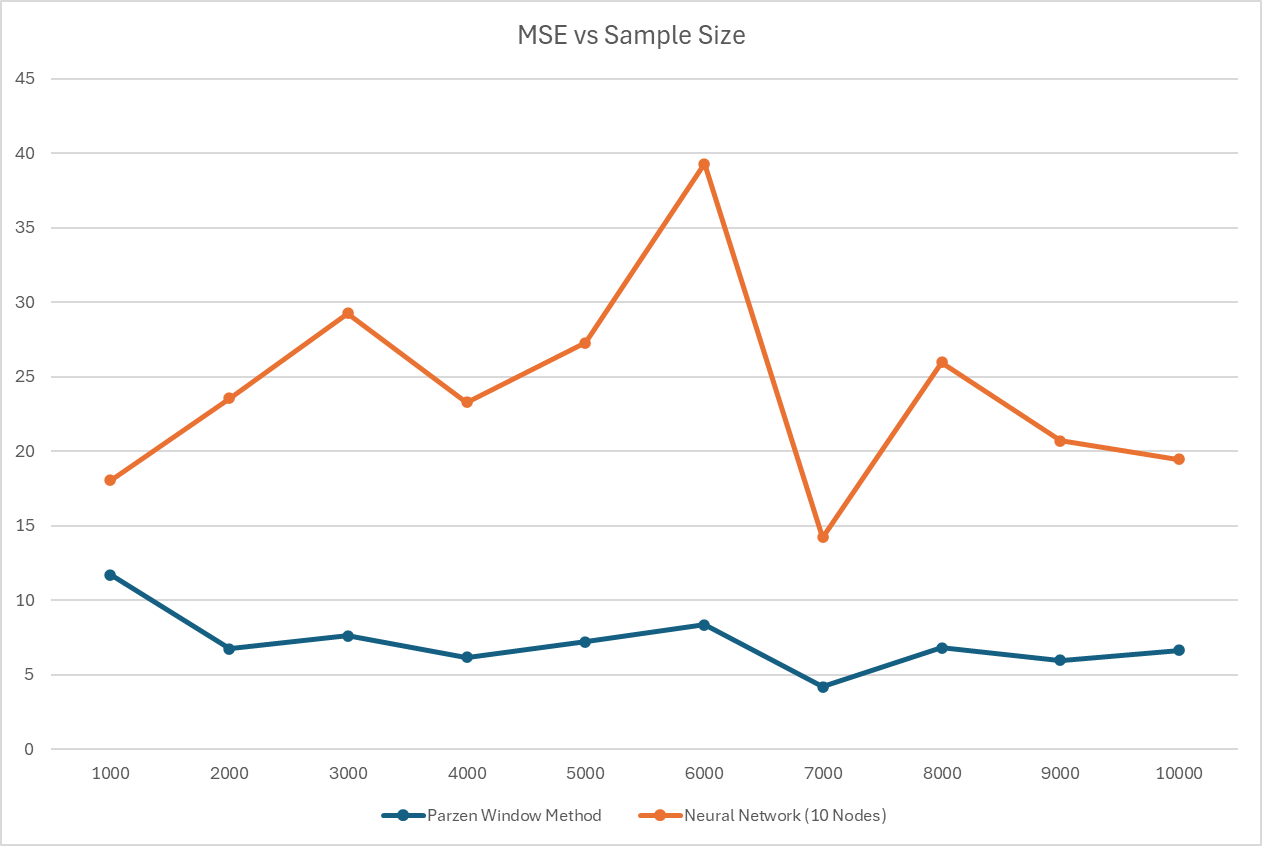

At a variance of 1, the results show that the PWE method consistently outperforms the NN model, with lower MSE values across all sample sizes. While the MSE for both models generally decreases as the sample size increases, the PWE model experiences a more significant improvement with larger datasets. For example, at a sample size of 1000, the PWE model’s MSE is 11.7223, while the NN model’s MSE is 18.0489. As the sample size increases to 10,000, the PWE model’s MSE reduces to 6.6656, while the NN model’s MSE only slightly decreases to 19.4780. The NN model’s MSE appears more erratic, with no clear trend of improvement. This pattern indicates that the PWE model scales more effectively with larger datasets, benefiting more from the increased data compared to the NN model.

To determine if a more distinct trend or pattern would emerge with higher variance, the same test was conducted again with a fixed variance of 2. After 10 epochs of localization processing for sample sizes of 1000 and 10,000, the average MSE was calculated for both models. The test was only run for these sample sizes due to time and computational resource constraints. The results are as follows:

At a variance of 2, the pattern observed is similar, although the MSE values are higher for both models. For a sample size of 1000, the PWE model’s MSE is 31.7682, while the NN model’s MSE is 71.4876. With a larger sample size of 10,000, the PWE model’s MSE decreases to 17.8135, while the NN model’s MSE is 87.5215. These results further reinforce the PWE model’s superior performance, particularly in handling increased signal noise and larger datasets, where its MSE remains significantly lower than the NN model's.

The results of this comparative testing demonstrate that the PWE method generally outperforms the NN model in terms of localization accuracy, both in terms of variance in the RSS vector and sample size. The PWE method shows robustness in environments with higher signal noise, maintaining lower MSE values across various conditions. Additionally, the PWE method benefits more from larger sample sizes compared to the NN model, suggesting that it may be a more efficient approach for localization tasks, especially when dealing with high levels of noise and large data sets. These findings validate the PWE method as a viable and efficient localization technique for signal processing applications.